# `Generating an uninformed partition of the state space`

**DONE**

    This function generates a tessellation of the set $X\setminus A$ (defined by limits in variables l(2,2) and xs(2,2)) made of triangle cells whose indices are stored in matrix C, with their vertices' coordinates in different matrices v, vx, vy and vr, and the inner and outer limits $\partial A$ and $\partial X$ in matrices dA(1,~) and dX(1,~) that contain indices respectively. A tessellation of $X\setminus A$ in our case is a partitioning of the set $X\setminus A$ into $N_c$ edge-to-edge cells $Y_c$ with $c=1,...,N_c$ taken for simplicity purposes as triangles. We end up with a set $\{Y_c\}\underset{c=1,...,N_c}$ such that :


$$\overline{X\setminus A} = \bigcup_{c=1}^{N_c} Y_c$$



$$c\neq c' \Longrightarrow \mathrm{int}(Y_c)\cap\mathrm{int}(Y_{c'}) = \O$$


There are two types generated :

- 'random' : has randomly distributed vertices on top of a mesh , the triangulation is Delaunay ;

- 'regular' : there are two meshes, one is a regular mesh from the edges, the second is made such that each of its vertices is in the center of a square made of the initial mesh's vertices. The triangulation is constructed such that the first mesh is made of squares, and the second mesh's vertices, being in the center of each of those squares, make a triangle with each side of the square.

***In  :***

- *matrix **l**(2,2) containing the limits inside which the vertices shall be generated (limits on the first dimension are in the first row and the lower limit in the first column)*

- *Nv**(1) the desired number of vertices*

- *matrix **l_A**(2,2) containing the limits of the attraction set *$A$* to exclude from the tessellation (limits on the first dimension are in the first row and the lower limit in the first column)*

- *parameter '**type**'(str='random','regular') specifying the type of tessellation we want to generate*

***Out :***

- *the triangulation **C**(*$N_c$*,3) containing the indices of vertices in each triangle*

- *vertices' matrix **v**(2,*$N_v$*) containing the coordinates of each vertex*

- *list **dA**(~,1) containing the index of vertices in the inner bound of *$X\setminus A$ ($\overline{X\setminus A}\cap\overline{A}$)*, and list **dX**(~,1) containing the index of vertices in the outer bound of *$X\setminus A$

- *Nv**(1) corresponding to *$N_v$* the number of vertices and **Nc**(1) corresponding to *$N_c$* the number of cells or triangles*

- *Tess**(PolyUnion) a polyunion of all the cells as polyhedrons*

function [C,v,dA,dX,Nv,Nc,Tess] = TessellationGenerator(l,Nv,l_A,type)

**Case 1 :** random.

    if contains(type,'random')

We define the coordinates of the vertices in the outer bound (dots in blue) :

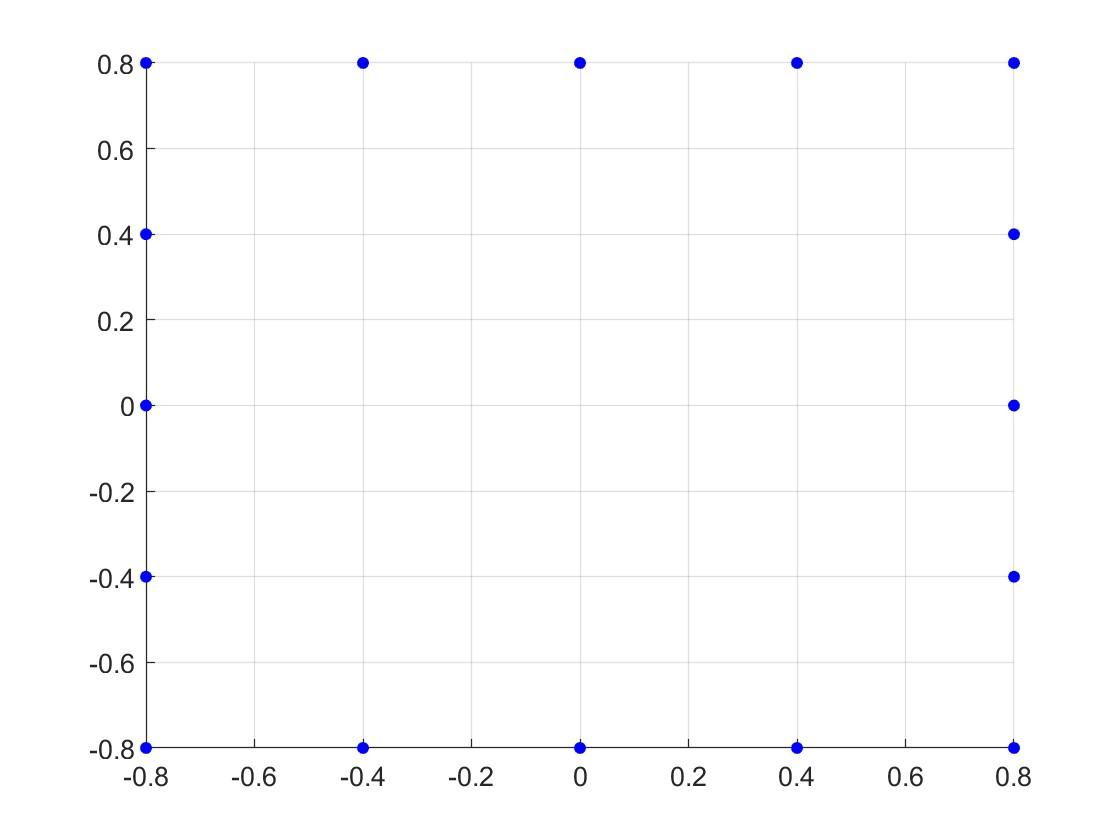

        outx1 = [l(1,1), l(1,1), l(1,1), l(1,1), l(1,1),... % x1 coordinates of the left side of the dX square
            l(1,2), l(1,2), l(1,2), l(1,2), l(1,2),...      % x1 coordinates of the right side of the dX square
            l(1,1)/2, 0, l(1,2)/2,...                       % x1 coordinates of the bottom side of the dX square
            l(1,1)/2, 0, l(1,2)/2];                         % x1 coordinates of the top side of the dX square
        outx2 = [l(2,1), l(2,1)/2, 0, l(2,2)/2, l(2,2),...  % x2 coordinates of the left side of the dX square
            l(2,1), l(2,1)/2, 0, l(2,2)/2, l(2,2),...       % x2 coordinates of the right side of the dX square
            l(2,1), l(2,1), l(2,1),...                      % x2 coordinates of the bottom side of the dX square
            l(2,2), l(2,2), l(2,2)];                        % x2 coordinates of the top side of the dX square

We define the coordinates of the vertices in the inner bound (dots in red) :

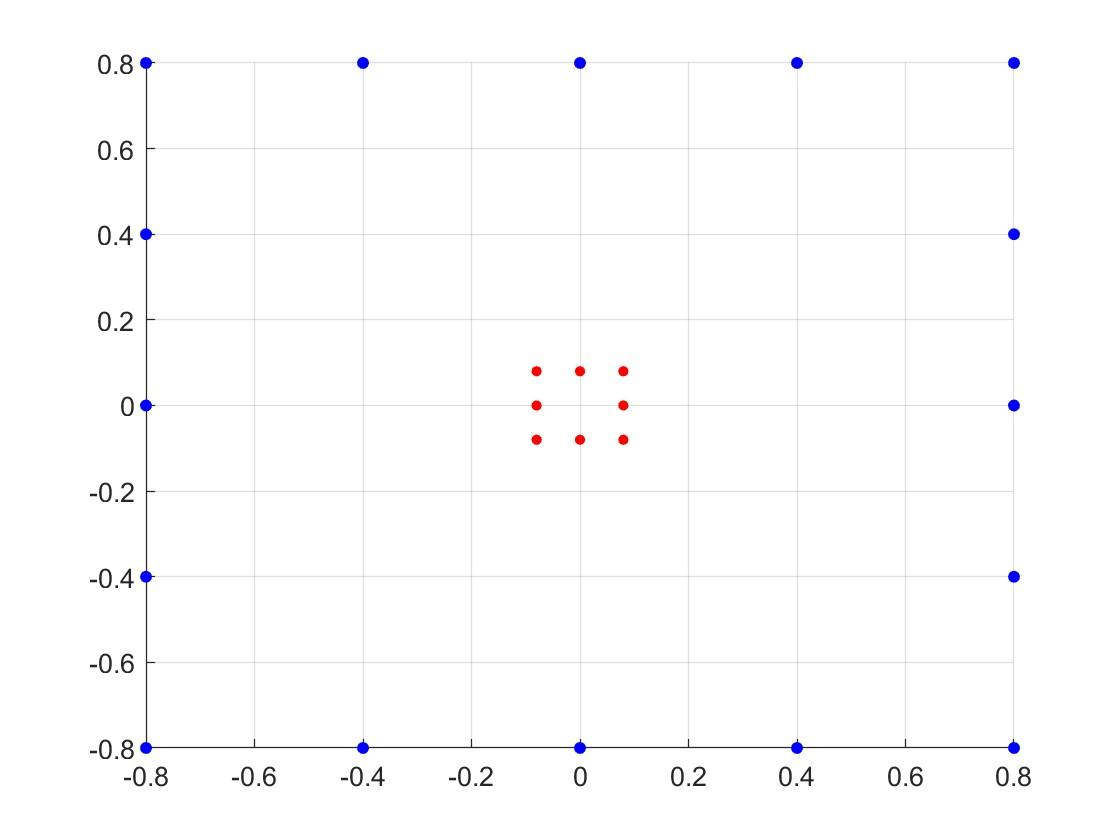

        inx1 = [l_A(1,1), 0, l_A(1,2), l_A(1,1), 0, l_A(1,2), l_A(1,1), l_A(1,2)]; % all of the x1 coordinates of the dA square
        inx2 = [l_A(2,1), l_A(2,1), l_A(2,1), l_A(2,2), l_A(2,2), l_A(2,2), 0, 0]; % all of the x2 coordinates of the dA square

We generate random points and add them in the list of coordinates to the inner and outer bounds (small dots in black) :

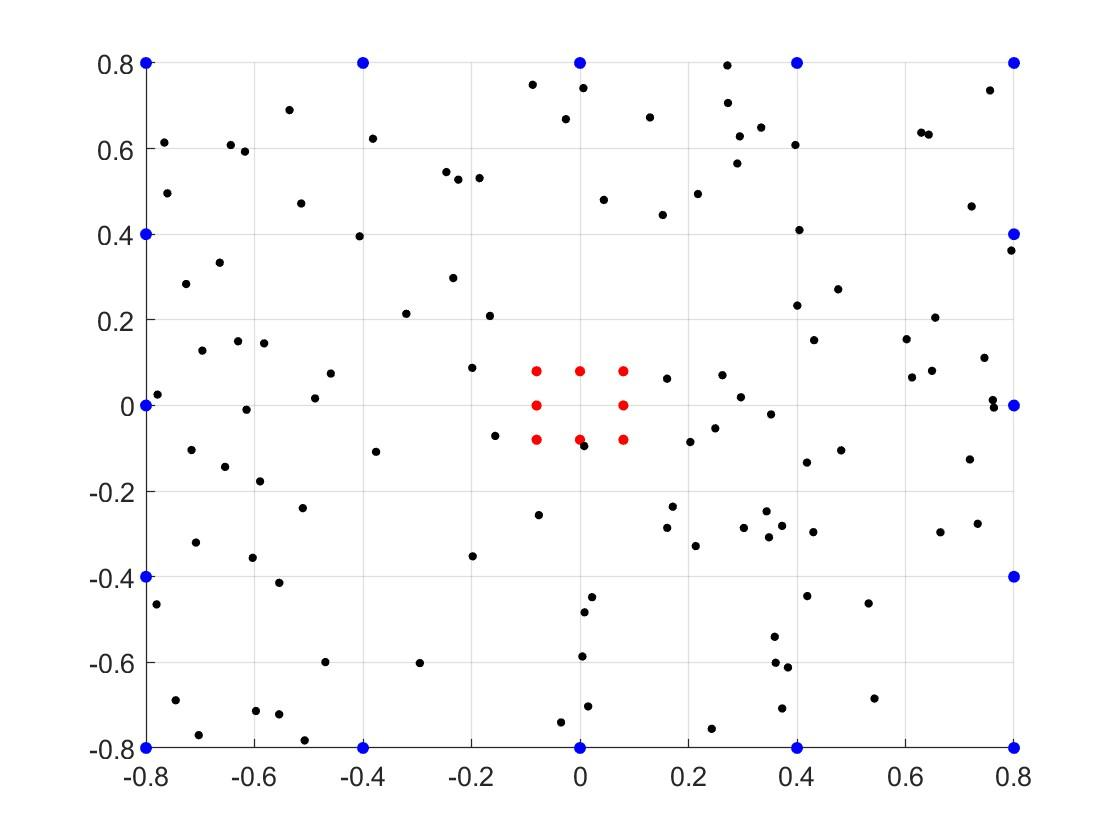

We also try to eliminate as well as possible the 

        vx1 = []; vx2 = []; k = 0; len = length(vx1);
        while len < Nv-24
            k = k+1
            vx1 = [vx1, l(1,1) + (l(1,2)-l(1,1))*rand(1,Nv-24)];
            vx2 = [vx2, l(2,1) + (l(2,2)-l(2,1))*rand(1,Nv-24)];
            cond1 = ((vx1(:)<l_A(1,2)) & (vx1(:)>l_A(1,1))) & ((vx2(:)<l_A(2,2)) & (vx2(:)>l_A(2,1)));
            vx1(cond1) = []; vx2(cond1) = [];
            u = 1;
            while true
                tempvar = (sum(([vx1(u);vx2(u)]-[vx1;vx2]).^2,1)).^0.5;
                tempvar(u) = [];
                if any(tempvar<=0.08)
                    vx1(u) = []; vx2(u) = [];
                end
                u = u+1;
                if u > length(vx1)
                        break
                end
            end
            len = length(vx1);
        end
        vx1 = [outx1, inx1, vx1];
        vx2 = [outx2, inx2, vx2];

We eliminate all randomly generated points inside $A$.

We construct the matrix of the vertices' coordinates v.

        v = [vx1; vx2];

Since we already now the indices of vertices in the bounds, we store them directly in dA and dX. There is another more general method used in the other tessellation type, but it works only if $X$ and $A$ are square because of the infinity norm, else it gives only a few of the expected bound points.

        dA = 17:24;
        dX = 1:16;

We construct the triangulation C using the Delaunay function and eliminate to the best the triangles formed inside $A$ :

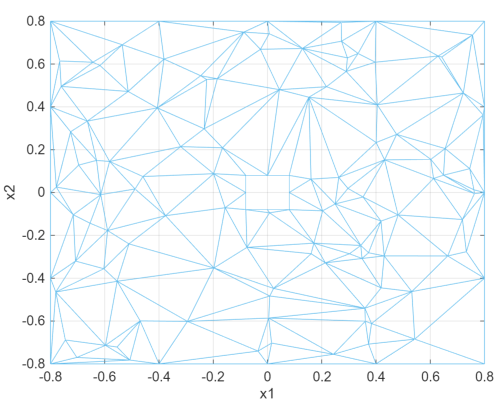

        C = delaunay(vx1,vx2);
        cond2 = (C(:,1)>=17 & C(:,1)<=24) & (C(:,2)>=17 & C(:,2)<=24) & (C(:,3)>=17 & C(:,3)<=24);
        C(cond2,:) = [];

**Case 2 :** regular.

    elseif contains(type,'regular')

Since the tessellation is regular in a specific shape, the number of vertices can only be {24,60,112,180,...}. So we compute the number of vertices in a line based on the initial desired number Nv in order to construct the meshes. This number is a solution of the equation $n^2+(n-1)^2 = N_v$, $n^2$ being the number of vertices in the first mesh, $(n-1)^2$ the number of vertices in the second mesh.

        number = floor((2*Nv - 1)^(1/2)/2 + 1/2);
        if mod(number,2)==1
            number = number+1;
        end

We construct the first mesh of vertices making up the squares (dots in blue) :

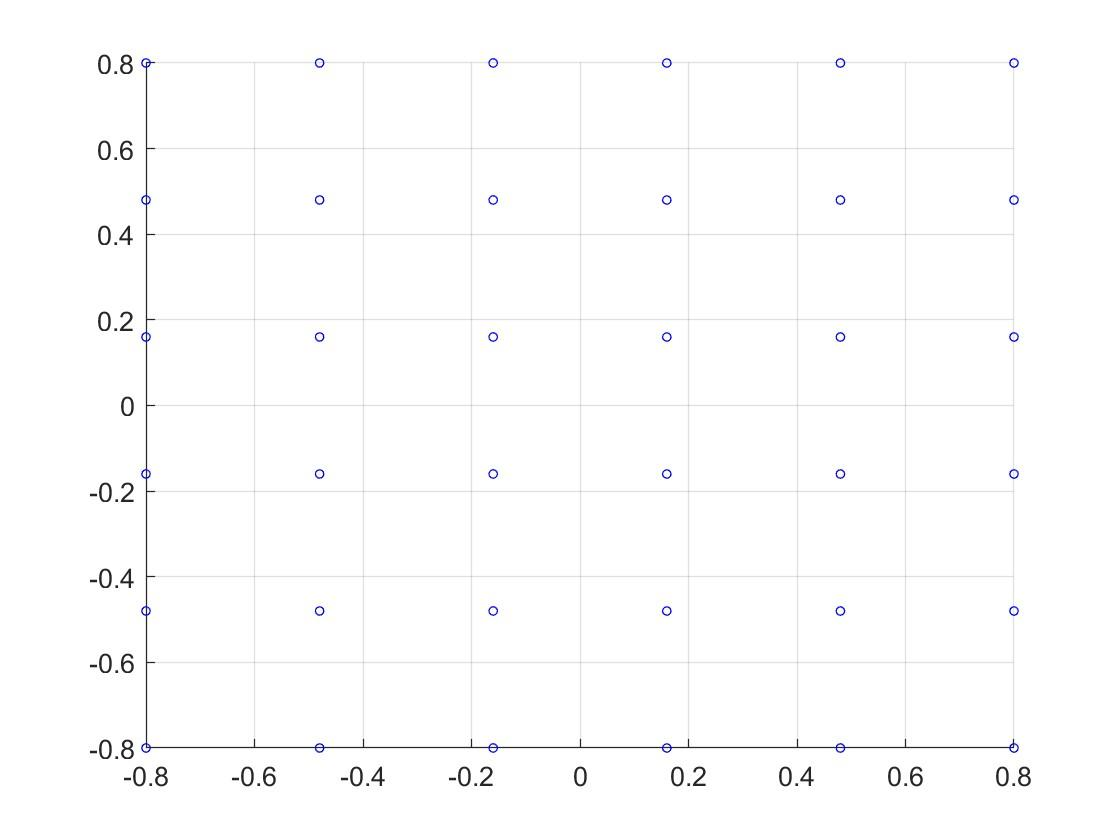

        [vx1,vy1] = meshgrid(l(1,1):(l(1,2)-l(1,1))/(number-1):l(1,2),l(2,1):(l(2,2)-l(2,1))/(number-1):l(2,2));
        svx1 = size(vx1); svy1 = size(vy1);

We construct the second mesh of vertices making up the centers of the squares (dots in red) :

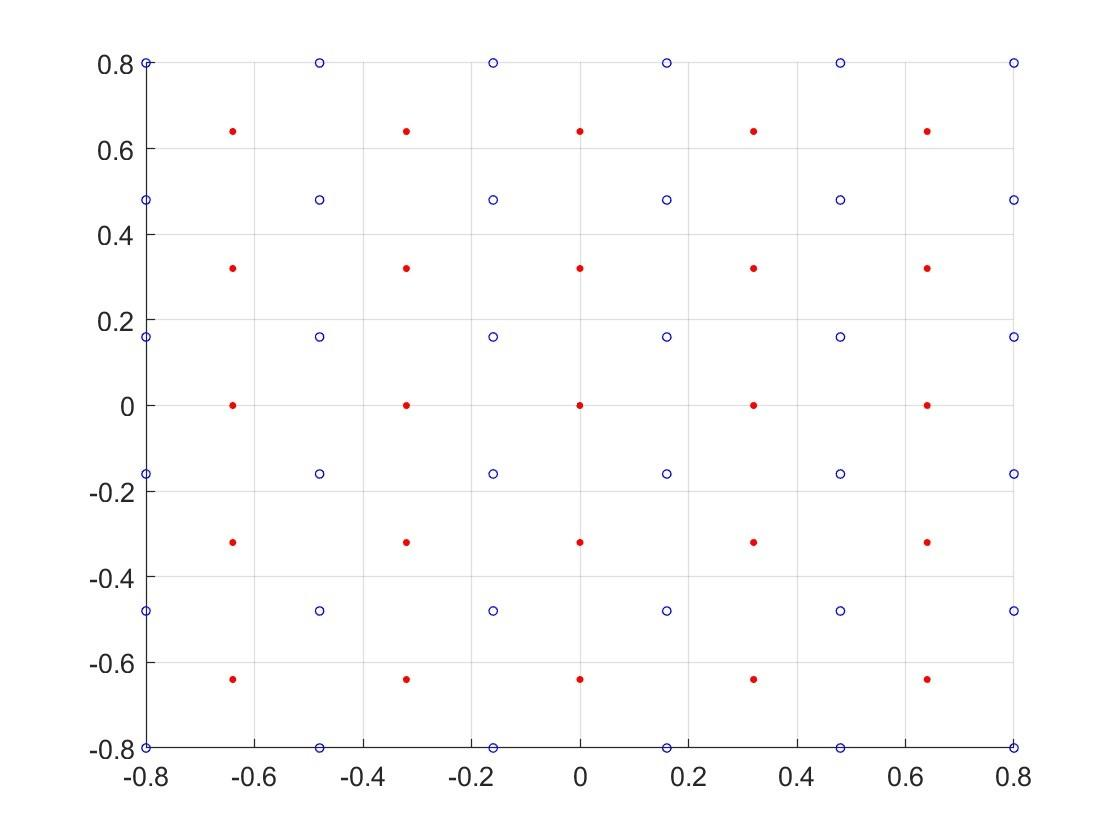

        [vx2,vy2] = meshgrid(l(1,1)+l(1,2)/(number-1):(l(1,2)-l(1,1))/(number-1):l(1,2)+l(1,1)/(number-1),l(2,1)+l(2,2)/(number-1):(l(2,2)-l(2,1))/(number-1):l(2,2)+l(2,1)/(number-1));
        svx2 = size(vx2); svy2 = size(vy2);

We put all the coordinates in one vector for each dimension.

        vx1 = [reshape(vx1,[1,svx1(1)*svx1(2)]), reshape(vx2,[1,svx2(1)*svx2(2)])];
        vx2 = [reshape(vy1,[1,svy1(1)*svy1(2)]), reshape(vy2,[1,svy2(1)*svy2(2)])];

We eliminate the equilibrium point [0,0] :

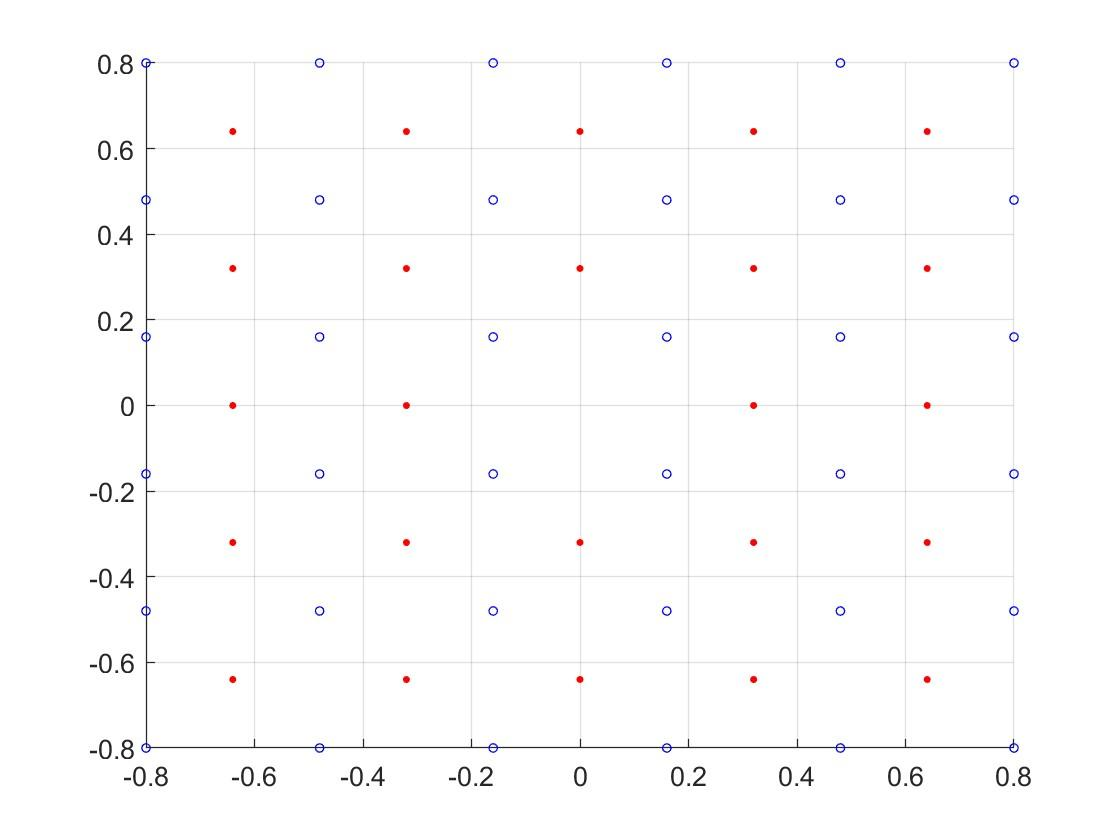

**N.B :** in the particular case of this tessellation, it is hard to eliminate $A$ with precision, so I opted to only eliminate the square that contains [0,0] regardless if this square represents $A$ or not. Basically, I redefine $A$ depending on the tessellation.

        cond1 = (vx1(:)==0) & (vx2(:)==0);
        index = find(cond1);
        vx1(cond1) = []; vx2(cond1) = [];

We construct the matrix of the vertices' coordinates v.

        v = [vx1; vx2];

We compute the infinity norm of each vertex and sort them, then keep the indices of the vertices with the lowest value in dA and the highest value in dX. Keep in mind that this method works only if $X$ and $A$ are square because of the infinity norm, else it gives only a few of the expected bound points.

        normx = zeros(length(v),2);
        for u = 1:length(v)
            normx(u,:) = [norm(v(:,u),inf), u];
        end
        normx = sortrows(normx);
        dA = normx(normx(:,1)==normx(1,1),2);
        dX = normx(normx(:,1)==normx(end,1),2);

We construct the regular triangulation square by square. We go from the left bottom square to the top, then go from one column of squares to the next one on the right and begin again from the bottom to the top, and so on.

        C = zeros(4*(number-1)^2-4,3);
        c = 1;
        for u = 1:number-1 % loop on the squares mesh
            for j = 1:number-1 % loop on the center of the squares mesh
                centerpoint = (u-1)*(number-1)+j+svx1(1)*svx1(2); % center point index

This part is for the squares on the columns to the left of $A$ and half the column under $A$.

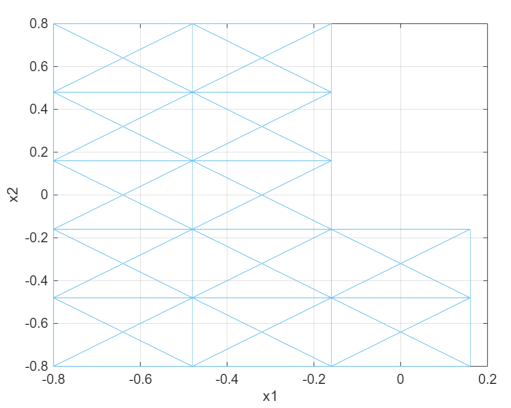

                if ((u-1)*(number-1)+j+svx1(1)*svx1(2) < index) && (u*number+j+1 < index)
                    C(c,1) = centerpoint; C(c,2) = (u-1)*number+j; C(c,3) = (u-1)*number+j+1; c = c+1;  % triangle on the left of the square
                    C(c,1) = centerpoint; C(c,2) = (u-1)*number+j+1; C(c,3) = u*number+j+1; c = c+1;    % triangle on the top of the square
                    C(c,1) = centerpoint; C(c,2) = u*number+j+1; C(c,3) = u*number+j; c = c+1;          % triangle on the right of the square
                    C(c,1) = centerpoint; C(c,2) = u*number+j; C(c,3) = (u-1)*number+j; c = c+1;        % triangle on the bottom of the square

This part is for the squares on the bottom of the rest of the columns.

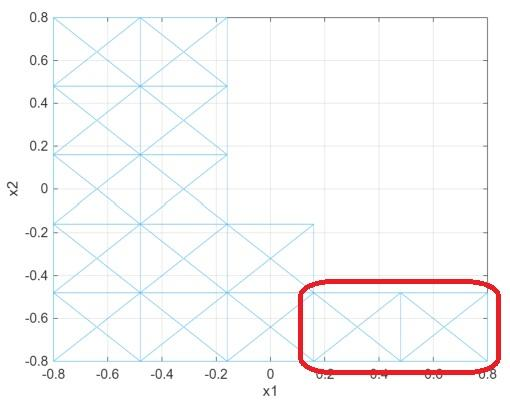

                elseif (j == number-1) && ((u-1)*(number-1)+j+svx1(1)*svx1(2) <= length(v))
                    C(c,1) = centerpoint; C(c,2) = (u-1)*number+j+2; C(c,3) = (u-1)*number+j+3; c = c+1; % triangle on the left of the square
                    C(c,1) = centerpoint; C(c,2) = (u-1)*number+j+3; C(c,3) = u*number+j+3; c = c+1;     % triangle on the top of the square
                    C(c,1) = centerpoint; C(c,2) = u*number+j+3; C(c,3) = u*number+j+2; c = c+1;         % triangle on the right of the square
                    C(c,1) = centerpoint; C(c,2) = u*number+j+2; C(c,3) = (u-1)*number+j+2; c = c+1;     % triangle on the bottom of the square

This part is for the rest of the squares.

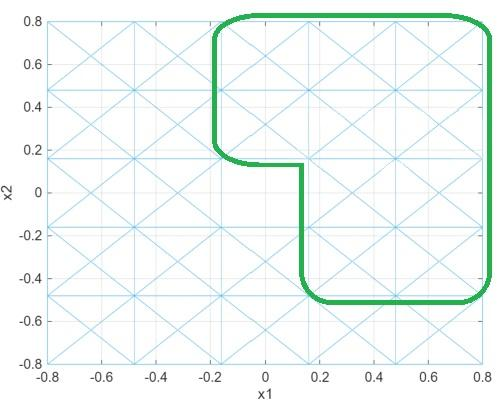

                elseif (u-1)*(number-1)+j+svx1(1)*svx1(2) <= length(v)
                    C(c,1) = centerpoint; C(c,2) = (u-1)*number+j+1; C(c,3) = (u-1)*number+j+2; c = c+1; % triangle on the left of the square
                    C(c,1) = centerpoint; C(c,2) = (u-1)*number+j+2; C(c,3) = u*number+j+2; c = c+1;     % triangle on the top of the square
                    C(c,1) = centerpoint; C(c,2) = u*number+j+2; C(c,3) = u*number+j+1; c = c+1;         % triangle on the right of the square
                    C(c,1) = centerpoint; C(c,2) = u*number+j+1; C(c,3) = (u-1)*number+j+1; c = c+1;     % triangle on the bottom of the square
                end
            end
        end
    end

We update the value of the number of vertices Nv and store the number of obtained cells in Nc.

    Nv = length(v);
    Nc = length(C);

We create the polyunion Tess containing all the cells as polyhedrons.

    for c = 1:length(C)
        Ptemp(c) = Polyhedron('V', [v(:,C(c,1))';v(:,C(c,2))';v(:,C(c,3))']);
    end
    Tess = PolyUnion(Ptemp).convexHull;

end